## Find TTI medium

tt = 101;

stress.xx = Results.stress_x(:,:,tt)'/1e6; 
stress.xz = Results.stress_xy(:,:,tt)'/1e6;
stress.zz = Results.stress_y(:,:,tt)'/1e6; 

% Get tilt angle
Theta = zeros(size(stress.xx));

for i=1:size(stress.xx,1)
    for j = 1:size(stress.xx,2)
        SM = zeros(3,3);
        SM(1,1) = stress.xx(i,j);
        SM(1,3) = stress.xz(i,j);
        SM(3,1) = SM(1,3);
        SM(3,3) = stress.zz(i,j);
        [R, theta] = get_Rotation_matrix(SM);
        Theta(i,j) = theta;
    end
end

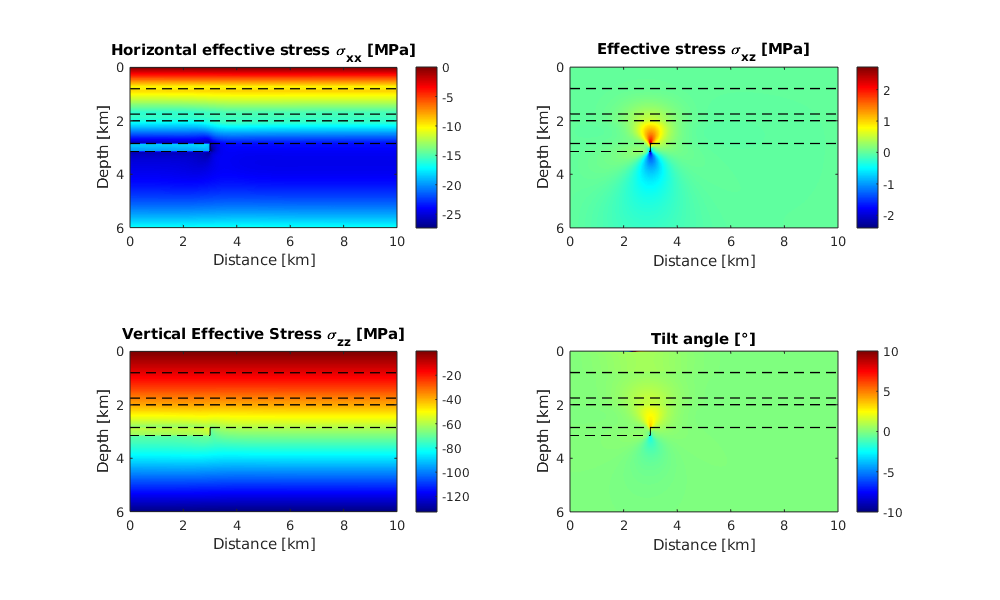


figure(223)
fig = figure('Position', [1 1 1000 600]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, stress.xx)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Horizontal effective stress \sigma_{xx} [MPa]')

subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, stress.xz)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Effective stress \sigma_{xz} [MPa]')


subplot(2,2,3)
imagesc(G.xx/1e3, G.zz/1e3, stress.zz)
colormap('jet')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical Effective Stress \sigma_{zz} [MPa]')

subplot(2,2,4)
imagesc(G.xx/1e3, G.zz/1e3, Theta*180/pi)
colormap('jet')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
caxis([-10 10])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Tilt angle [\circ]')